We would like to verify the conversions of data readouts from the force sensor.

clear
force = load("Lean Angles\Lean_12_Feb27_2025_test_3.mat").table_to_save;
release = load("Lean Angles\Lean_12_Feb27_2025_test_3_markers.mat").table_to_save;


% Inclinometer Measured Lean Angle Approx
leanAngles_Incl = [15 7 3 5 9 13 15 11 9 7 11 12];

% Estimate Lean Angle by the geometric model implemented in the MATLAB
% Tethered_Release_Lean_Feedback App
g = 9.80665;
m = 68; % 150 lbs
H = 1.62; % in meters
alpha = 0.65;
h = 1.1; % in meters
data_vec_F = force.("Raw Formatted Data")(2 : end);
est_force = (data_vec_F / 1e6) * 30 * 0.453592 * g; % uV to V to lbs to kg
est_lean_angle = abs(asin((est_force * h) / (m * g * H * alpha))) / pi * 180;
est_lean_angle_f = lowpass(est_lean_angle, 1, 500);


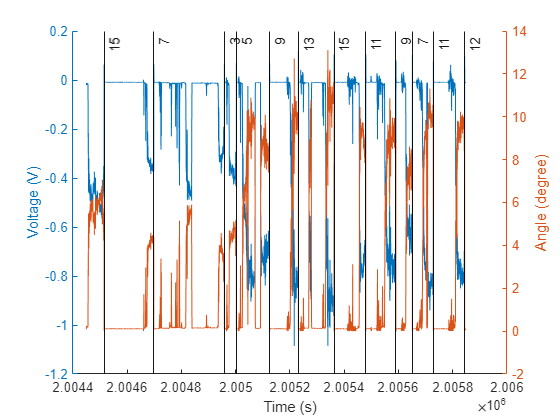

figure
hold on
yyaxis left
plot(force.("Time Stamps")(2 : end), data_vec_F / 1e6); % convert uV to V
ylabel("Voltage (V)")
yyaxis right
plot(force.("Time Stamps")(2 : end), est_lean_angle_f);
for i = 2 : 25
    xline(release.("Time Stamps")(i), "k", num2str(leanAngles_Incl(floor(i / 2))));
end
xlabel("Time (s)")
ylabel("Angle (degree)")